# **EEEE 1041  - Contemporary Engineering Themes A - Sample Exercise 2022_23**

## Coursework Exercise - MATLAB live notebook template

**NOTE: All function definitions ****must**** be placed at the end of the file in the Functions section provided**

***IMPORTANT***: For this coursework you should make sure that you use a parallel pool size (i.e. number of workers) equal to the number of physical cores on your machine. It is up you to determine how to do this in code by consulting the relevant MATLAB documentation but your code should be such that if run on a different machine it will automatically adapt to the number of cores available. You must also display the number of cores available.

% Write your code to display the number of cores and set up a parallel pool based on this here:
%
% Note: The code should check for an existing pool - if one exists it
% should stop this pool and create a new one.
% 

## **Excercise 1 - 20% of the mark**

Modify your pre-assessment code to work for **SIX** dice 

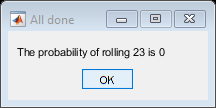

% Write your code here: - it should expand on the code provided (which MUST
% not be changed). 

NumberToTest = inputdlg ("Please enter the sum of dice value for which you are seeking the probabilty of this number being rolled");
NumberToTest = str2num(NumberToTest{1});

RollProbability = 0.0;        % This is where you must store your result

% ===================== Your code goes here



% ===================== You MUST NOT change the code beyond this point
% 

% Display answer
Message = (['The probability of rolling ', num2str(NumberToTest), ' is ', num2str(RollProbability)]);
f = msgbox(Message,"All done","modal");

## Questions:

1. What is the probability of rolling a 23?

*[Write your answer here]*

**Note**: Later exercises will refer to this value - there is no need to recalculate it, the value obtained here can be used directly within any calculations.

2. If instead we let the user select the number of dice to be thrown a technique that could be used to solve the problem is *recursion* - what is a disadvantage with is approach?

*[Write your answer here]*

## Exercise 2 - 40% of the mark

Monte-Carlo simulation is a technique that can be used to model the probability of outcomes based on repeated random sampling. Note: No previous knowledge of this method is however required to undertake this question.

You will be applying the technique to determine the probability of a certain value being obtained from the rolling of a number of dice. The approach is as below:

- Ask the user how many iterations they wish to perform (i.e. how many times to repeat the process). Store this value as ***M***.

- Ask the user how many dice are to be thrown, store this a ***N***.

- Ask the user which throw sum they wish the probability for, store this as ***Throw***

- Generate ***N*** random numbers in the range 1-6 (*d­1**, d**2**…, d**N*).

- Obtain the roll total by summing the values of each die and store this value in ***D*** 

- If the value of ***D*** is equal to ***Throw ***increase a counter ***C*** by one

- Repeat from (4) until*** M ***iterations have been completed.

The probability of throwing a specific value ***Throw ***is calculated as 

            Probability = (***C*** / ***M*** ) * 100

## The Matlab code to be developed

You are required to develop Matlab Code that prompts the user for the number of iterations ***M***, the number of dice to roll ***N*** and the value of a ***Throw*** for which a probability is required, this probability value being displayed to the user.

- 	A simple serial ‘for loop’ based approach	10%	

- 	Using a parfor loop				                10%	

- 	Using spmd                        			        20%

*Note*: In addition to displaying the probability plot your script should also display the time the process took to execute.

Each version should be in the relevant section of the workbook

# 1. A simple serial 'for loop' approach (10%)

Using the algorithm given in the instructions, write a serial for-loop approach to the problem. *Note:* faster implementations are of course possible using MATLAB array syntax, but we are interested in examining principles of parallelisation so please implement the algorithm as provided.

% Write your code here: - it should expand on the code provided (which MUST
% not be changed). 

NumberToTest = inputdlg ("Please enter the sum of dice value for which you are seeking the probabilty of this number being rolled");
NumberToTest = str2num(NumberToTest{1});

RollProbability = 0.0;        % This is where you must store your result

% ===================== Your code goes here


%
% ======= The code here must YOUR CODE that displays the run time
% 


%
% ===================== You MUST NOT change the code beyond this point
% 

% Display answer
Message = (['Serial Approach: The probability of rolling ', num2str(NumberToTest), ' is ', num2str(RollProbability)]);
f = msgbox(Message,"All done","modal");


## Questions:

1.1. How many iterations are required to get a value for the probability of throwing a value of 23 that is within 5% of the value obtained from exercise 1? *Note*: this value does need not be recalculated, the value can be used directly.

 [*Write your answer here]*

1.2. How many itteratations are required to get a value for the probability of throwing a value of 23 that is within 0.1% of the value obtained from exercise 1? *Note: *this value does need not be recalculated, the value can be used directly.

*[Write your answer here]*

***NOTE****: Later sections will refer to these calculated values - there is no need to recaulate them, the values obtained can be used directly within any calculaions.*

# 2. Using a parfor loop (10%)

This section is for the version that uses a parfor loop. The code should use as many workers as there are physical cores on a machine and should be able to adapt appropriately when run on another machine.

% Write your code here: - it should expand on the code provided (which MUST
% not be changed). 

NumberToTest = inputdlg ("Please enter the sum of dice value for which you are seeking the probabilty of this number being rolled");
NumberToTest = str2num(NumberToTest{1});

RollProbability = 0.0;        % This is where you must store your result

% ===================== Your code goes here
% Note: The 1st task should be to start a pool (if necessary) and report on the number
% of workers


%
% ======= The code here must YOUR CODE that displays the run time
% 


%
% ===================== You MUST NOT change the code beyond this point
% 

% Display answer
Message = (['PARFOR Approach: The probability of rolling ', num2str(NumberToTest), ' is ', num2str(RollProbability)]);
f = msgbox(Message,"All done","modal");


## Questions:

2.1. Which of the 'for' or 'parfor' approaches is fastest in obtaining a value for the probability of throwing a 23 that is within 5% of the value obtained from exercise 1? Why is this?

* [Write your answer here]*

2.2. Which of the 'for' or 'parfor' approaches is fastest in obtaining a value for the probability of throwing a 23 that is with 0.1% of the value obtained from exercise 1? Why is this?

*[Write your answer here]*

# 3. Using SPMD (20%)

This section is for the version that uses SPMD.  The code should use as many workers as there are physical cores on a machine and should be able to adapt appropriately when run on another machine.

% Write your code here: - it should expand on the code provided (which MUST
% not be changed). 

NumberToTest = inputdlg ("Please enter the sum of dice value for which you are seeking the probabilty of this number being rolled");
NumberToTest = str2num(NumberToTest{1});

RollProbability = 0.0;        % This is where you must store your result

% ===================== Your code goes here
% Note: The 1st task should be to start a pool (if necessary) and report on the number
% of workers


%
% ======= The code here must YOUR CODE that displays the run time
% 


%
% ===================== You MUST NOT change the code beyond this point
% 

% Display answer
Message = (['SPMD Approach: The probability of rolling ', num2str(NumberToTest), ' is ', num2str(RollProbability)]);
f = msgbox(Message,"All done","modal");


## Questions:

3.1.  If you were to set your parallel pool to size `nCores+1 `where `nCores` is the number of physical cores on your machine, how would this affect speed of execution when obtaining a value for the probability of throwing a 23 that is with 0.1% of the value obtained in exercise 1? Justify your answer.

*[Write your answer here]*

3.2. If you were to set your parallel pool to size `nCores-1 `where `nCores` is the number of physical cores on your machine, how would this affect speed of execution when obtaining a value for the probability of throwing a 23 that is with 0.1% of the value obtained in exercise 1? Justify your answer.

*[Write your answer here]*

3.3 When obtaining a value for the probability of throwing a 23 that is with 0.1% of the value obtained in exercise 1, which is faster: `spmd` or `parfor`? Justify your answer.

*[Write your answer here]*

## Functions

If you wish to use functions as part of your solution they MUST be placed in this block

% Write your function(s) here:
